## **Skin-Stringer Panel Design**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

### **0 Design Parameters**

**0.1 Sea Level**

[T0, a0, P0, rho0] = atmosisa(0);  % Sea level condition
g = 9.80665;                       % Standard acceleration of gravity (m/s^2)

**0.2 Fuselage Properties**

D = 6.38;                          % Fuselage diameter (m)
r = D / 2;                         % Fuselage radius (m)
C = 2 * pi * r;                    % Circumference (m)

**0.3 Material Properties**

Skin (2024 T861)

sigma_skin = 455;                  % Tensile yield stress (MPa)
tau_skin = sigma_skin ./ sqrt(3);  % Shear yield stress (MPa)
rho_skin = 2780;                   % Density (kg/m^3)

Stringer (7068 T6511)

sigma_st = 683;                    % Tensile yield stress (MPa)
tau_st = sigma_st ./ sqrt(3);      % Shear yield stress (MPa)
rho_st = 2850;                     % Density (kg/m^3)

**0.4 Critical Loading Conditions**

Q = 5.951582721709430e+05;         % Maximum shear force (N)
P = 0;                             % Maximum tangential load (N)
M = -5.067912648168767e+06;        % Maximum bending moment (Nm)
T = 1.263599895277778e+06;         % Maximum torque (Nm)

### **1 Optimisation Problem using fmincon with Global research**

compare [fmincon](https://www.mathworks.com/help/optim/ug/fmincon.html) with [GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html) and [ga](https://ww2.mathworks.cn/help/gads/ga.html), using the best result

**1.0 Initial conditions**

Define the objective function for optimisation problem

fun = @(x) mass(x(1), x(2), x(3), x(4));        % (t_skin, s_st, t_st, L_st)

Define initial point for the objective function

x0 = [3 / 1000, 0.16, 3 / 1000, 15 / 1000];    % take average from literiture review

Boundary conditions

lb = [1 / 1000, 0.10, 1 / 1000, 1 / 1000];      % change dynamically
ub = [10 / 1000, 0.50, 10 / 1000, 50 / 1000];   % change dynamically

Nonlinear constraints

nonlcon = @Non_linear;

**1.1 Define problem**

Create optimization problem [createOptimProblem](https://ww2.mathworks.cn/help/gads/createoptimproblem.html)

problem = createOptimProblem('fmincon', 'objective', fun, 'x0', x0, 'lb', lb, 'ub', ub, 'nonlcon', nonlcon, 'options', optimoptions('fmincon', 'Display', 'iter'));

[GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html)

gs = GlobalSearch('NumTrialPoints', 1000, 'MaxWaitCycle', 100);

**1.2 Run optimisation**

[x_opt, f_opt] = fmincon(fun, x0, [], [], [], [], lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_opt =     0.0024    0.1592    0.0014    0.0154


f_opt = 176.4420

[x_opt, f_opt] = run(gs, problem)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    3.696309e+02    0.000e+00    5.043e+03
    1      31    3.696308e+02    0.000e+00    5.043e+03    1.009e-08
    2      37    3.696283e+02    0.000e+00    5.043e+03    5.675e-07
    3      43    2.432597e+02    6.144e-03    5.269e+03    2.946e-03
Nonlinear constraint function returned NaN; trying a new point...
    4      58    2.181636e+02    0.000e+00    3.191e+03    9.011e-04
Nonlinear constraint function returned NaN; trying a new point...
    5      72    2.143226e+02    0.000e+00    6.079e+02    1.015e-02
    6      81    2.033327e+02    0.000e+00    2.377e+02    7.020e-03
    7      87    1.950176e+02    0.000e+00    4.291e+04    5.696e-03
    8     118    1.950161e+02    0.000e+00    2.948e+04    9.302e-07
Nonlinear constraint function returned NaN; trying a new point...
    9     124    1.950157e+02    0.000e+00    2.948e+04 

x_opt =     0.0024    0.1592    0.0014    0.0154


f_opt = 176.4420

### **2 Validate Result**

**2.1 Assign x values**

t_skin = x_opt(1); % skin thickness (m)
t_skin * 1000      % Typically 1 mm to 10 mm

ans = 2.4152

s_st = x_opt(2);   % stringer spacing (m)
s_st               % Typically 0.20 m

s_st = 0.1592

t_st = x_opt(3);   % stringer thickness (m)
t_st * 1000        % Typically 2 mm

ans = 1.4454

L_st = x_opt(4);   % stringer flange (m)
L_st * 1000        % Typically 15 mm

ans = 15.3710

h_st = L_st / 0.3; % stringer height (m)
h_st * 1000        % Typically 30 mm

ans = 51.2366

**2.2 Calcualte mass per unit length**

% Calcualte Z-shaped stringer area (m^2)
B_st = 2 * (L_st * t_st) + (h_st - 2 * t_st) * t_st

B_st = 1.1431e-04

B_st * 1000 ^ 2

ans = 114.3140

% Calcualte total Z-shaped stringer mass per unit length (kg/m)
m_st = rho_st * B_st * (C / s_st)

m_st = 41.0094

% Calcualte skin mass per unit length (kg/m)
m_skin = rho_skin * (C * t_skin)

m_skin = 134.5786

% Mass per unit length (kg/m)
m_l = m_st + m_skin

m_l = 175.5880

**2.3 Validate design value**

% Recall the initial design parameters inside the function
D = 6.38;
r = D / 2;
C = 2 * pi * r;
E = 71300000000;
E_st = 71700000000;
q_st = s_st;
% q_st = s_st - L_st;
sigma_skin = 455000000;

% From ESDU datasheet 
% (see Structure 3 Lecture Notes for k to K calculation)
Kc = 3.69; % 3.62 for v = 0.3
Ks = 4.93; % 4.83 for v = 0.3

% Recall the initial design parameters inside the function
% Q = 5.951582721709430e+05;  % Maximum shear force (N)
% P = 0;                      % Maximum tangential load (N)
M = -5.067912648168767e+06;   % Maximum bending moment (Nm)
% T = 1.263599895277778e+06;  % Maximum torque (Nm)

% Recall the maximum shear flow
q = 7.914986682604700e+04;    % Maximum shear flow (Nm)

% Find the number of the stringer
n = ceil(C / s_st)            % Round-up for safety

n = 126

s_st = C / n

s_st = 0.1591


% Compute the stringer section area
B_st = 2 * (L_st * t_st) + (h_st - 2 * t_st) * t_st;

% Find the y-location for each case
y = zeros(1, n);

for i = 1 : n

    y(i) = r * sin((2 * pi * (i - 1)) / n);

end

% Compute the skin collaborative area
B_i = zeros(1, n);

B_i(1) = (t_skin * s_st / 6) * (2 + y(end) / y(1)) + ...
    (t_skin * s_st / 6) * (2 + y(2) / y(1)); % First stringer
B_i(n) = (t_skin * s_st / 6) * (2 + y(n-1) / y(n)) + ...
    (t_skin * s_st / 6) * (2 + y(1) / y(n)); % Last stringer

for i = 2 : n - 1

    B_i(i) = (t_skin * s_st / 6) * (2 + y(i-1) / y(i)) + ... 
        (t_skin * s_st / 6) * (2 + y(i+1) / y(i));

end

B_i(1) = B_i(n);

% Compute total boom area for each stringer
B_total = zeros(1, n);

for i = 1 : n

    B_total(i) = B_st + B_i(i);

end

% Compute the second moment of area, Ix
I_x = 0;

for i = 1 : n

    I_x = I_x + B_total(i) * (y(i) ^ 2);

end

% Find the shear stress distribution
sigma = zeros(1, n);

for i = 1 : n

    sigma(i) = (M / I_x) * y(i);

end

% Find the maximum tensile stress
sigma_ten = abs(min(sigma));
sigma_ten / 1e6

ans = 50.5850


% Find the maximum bending & compression stress
sigma_ben = abs(max(sigma));
sigma_ben / 1e6

ans = 50.5850


% Find the maximum shear stress
shear = q / t_skin

shear = 3.2771e+07

shear / 1e6

ans = 32.7710


% Critical buckling stress of the skin
shear_crit = Ks * E * ((t_skin / q_st) ^ 2);
shear_crit / 1e6

ans = 80.8715


sigma_crit = Kc * E * ((t_skin / q_st) ^ 2);
sigma_crit / 1e6

ans = 60.5306


% Critical buckling stress of the stringer
sigma_crit_st = Kc * E_st * ((t_st / h_st) ^ 2);

sigma_crit_st  / 1e6

ans = 210.5543


% Find Farrar's efficiency
As_bt = B_st / (s_st * t_skin);
ts_t = t_st / t_skin;
Farrar = interpF(As_bt, ts_t);

% Compute Total Panel Moment of Inertia
% I_total = I_stringer * n + I_skin;

% Define the inequality constriant
%
% tensile stress
sigma_ten - sigma_skin;

% compression-shear interaction
(shear / shear_crit) ^ 2 + sigma_ben / sigma_crit

ans = 0.9999


% Critical buckling stress of the stringer
sigma_ben - sigma_crit_st;

% boundary for stringer design
h_st - 2 * t_st 

ans = 0.0483


% Farrar's efficiency
As_bt

As_bt = 0.2975

ts_t

ts_t = 0.5985

Farrar

Farrar = 0.6500


% Define the equality constraint
%
% stringer must be uniformly spacing
ceq = mod(C, s_st) / C

ceq = 0

**2.3 Save data**

save('x.mat', 'x_opt')

### **A Functions**

**A.1 Calculate skin-stringer panel mass per unit length**

% t_skin = 1 / 1000; % Skin thickness (m)

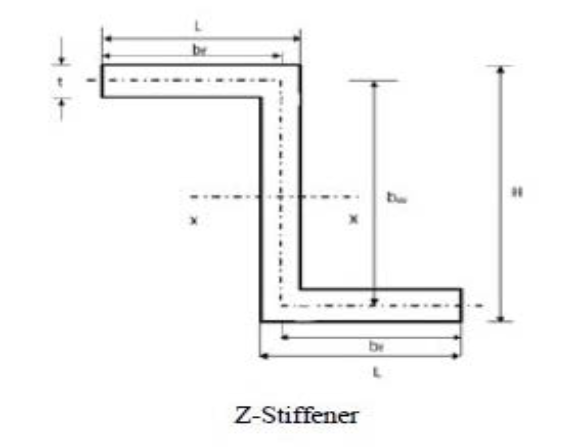

See the 'Fuselage Design' Excel sheet

% s_st = ;           % Stringer spacing (m)
% t_st = ;           % Stringer thickness (m)
% L_st = ;           % Stringer flange (m)
% h_st = ;           % Stringer height (m)

*The optimisation goal is to minimise the total mass, the price of the material is not considered for simplicity of the preliminary design.*

*In addition, lower weight would reduce costs in terms of fuel and give aircraft more design redundencoes.*

% function m_l = mass(t_skin, s_st, t_st, L_st, h_st)

**A.2 Non-linear constriant**

See the Structure 3 Lecture Notes about Interactive buckling in plates

**A.3 Genetic Algorithm**

% function [c, ceq] = Non_linear(x)
% Define the number of variables
% numVars = 5; % (t_skin, s_st, t_st, L_st, h_st)

% define Genetic Algorithm options
% options = optimoptions('ga', ...
    % 'PopulationSize', 1000, ...       % Population size (adjust for convergence speed)
    % 'MaxGenerations', 2000, ...       % Maximum generations to evolve
    % 'CrossoverFraction', 0.8, ...    % Probability of crossover
    % 'MutationFcn', @mutationadaptfeasible, ... % Adaptive mutation
    % 'Display', 'iter', ...           % Display iteration info
    % 'UseParallel', true);            % Enable parallel processing (if available)

% Run Genetic Algorithm
% [x_opt, f_opt] = ga(@(x) mass(x(1), x(2), x(3), x(4), x(5)), ...
    % numVars, [], [], [], [], lb, ub, nonlcon, options)